**Solving the heat equation**

x = linspace(0,1,200);
t = linspace(0,10,201);

**solving pde using pdepe()**

heat_answer = pdepe(0, @set_coefficients, @IC_definer, @BC_definer, x, t);

**show temperature in t = [0, 5, 10]**

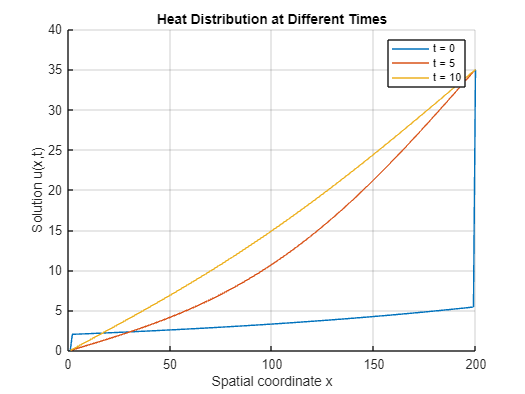

figure;
hold on;
plot(heat_answer(1,:), 'DisplayName', 't = 0');
plot(heat_answer(101,:), 'DisplayName', 't = 5');
plot(heat_answer(201,:), 'DisplayName', 't = 10');
hold off;

xlabel('Spatial coordinate x');
ylabel('Solution u(x,t)');
title('Heat Distribution at Different Times');
legend show;
grid on;

همانطور که روی نمودار مشخص است در لحظه 0 دمای همه نقاط میله بجز انتهای آن 0 است و انتهای آن 50 است که با توجه به شرایط مرزی این موضوع روشن است ولی هر چه زممان می گذرد این حرارات در طول میله پخش می شود به طوری که در لحظه 10 دمای میانی میله تقریبا به عدد 15 رسیده است.علاوه بر آن می توان گفت که در زمان 5 منحنی اندکی خمیده است ولی در زمان 10 تقریبا خطی است که این نشان دهنده به تعادل رسیدن میله است.

**show 2-d temperature over space and time **

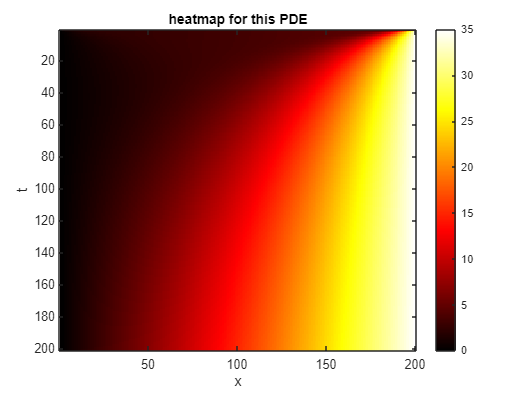

imagesc(heat_answer)
colormap hot
colorbar
xlabel('x');
ylabel('t');
title('heatmap for this PDE');

با توجه به نمدار رسم شده در اول کار حرارت در انتهای میله متمرکز است ولی هرچه در بعد زمان به سمت جلو حرکت می کنیم حرارت در سرتاسر میله شروع به پخش شدن می کند به طوری که در ابتدا تنها انتهای میلهرنگ روشن دارد و بقیه میله تقریبا رنگ تیره دارد ولی مثلا در زمان 200 روشنی از انتهای میله به سمت ابتدای آن پخش شده است که نشان دهنده پخش حرارت و به تعادل رسیدن آن است.

**change x and t**

second_x = linspace(0,1,100);
second_t = linspace(0,10,101);

second_heat_answer = pdepe(0, @set_coefficients, @IC_definer, @BC_definer, second_x, second_t);

**show 3-d plot**

**first**

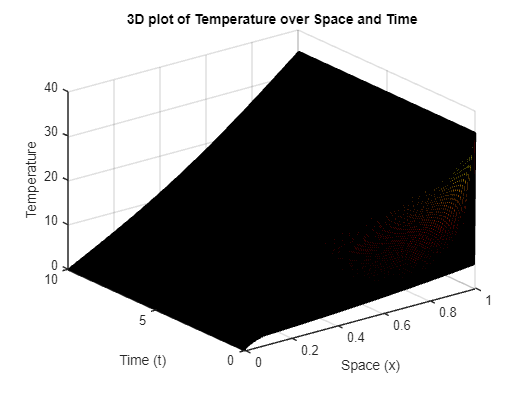

figure;
surf(x, t, heat_answer);
colormap hot
xlabel('Space (x)');
ylabel('Time (t)');
zlabel('Temperature');
title('3D plot of Temperature over Space and Time');

**second**

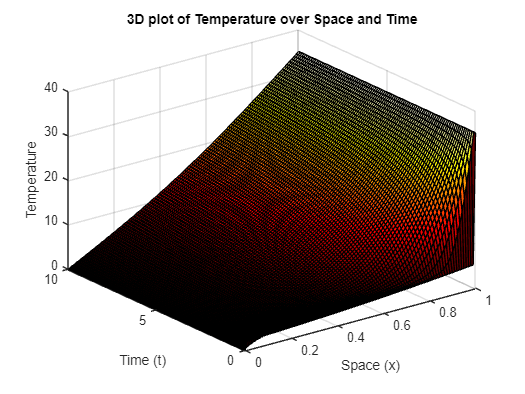

figure;
surf(second_x, second_t, second_heat_answer);
colormap hot
xlabel('Space (x)');
ylabel('Time (t)');
zlabel('Temperature');
title('3D plot of Temperature over Space and Time');

**Solving the helmholts equation**

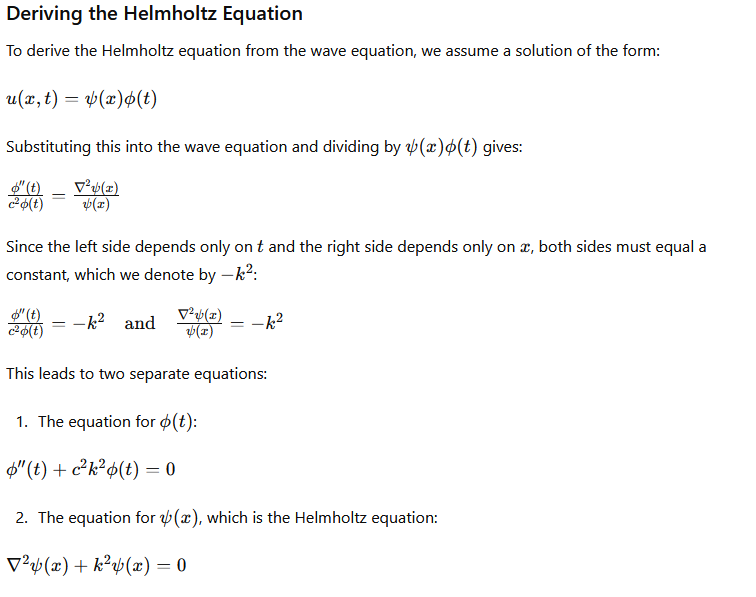

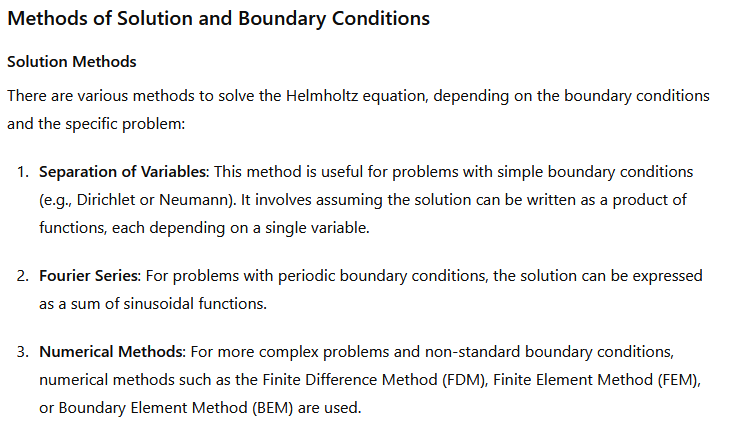

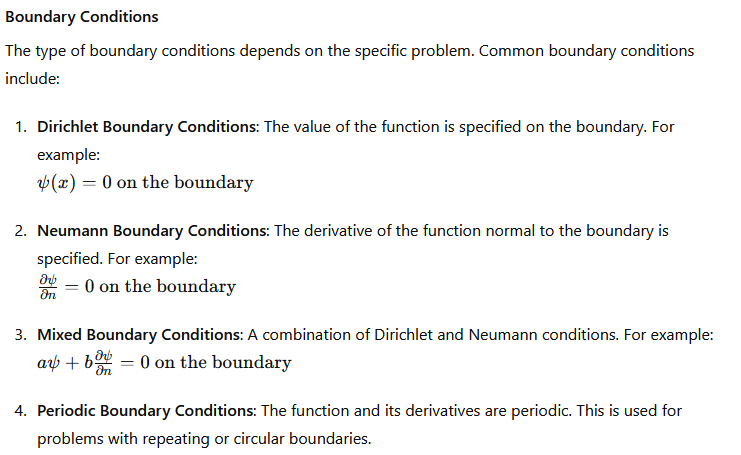

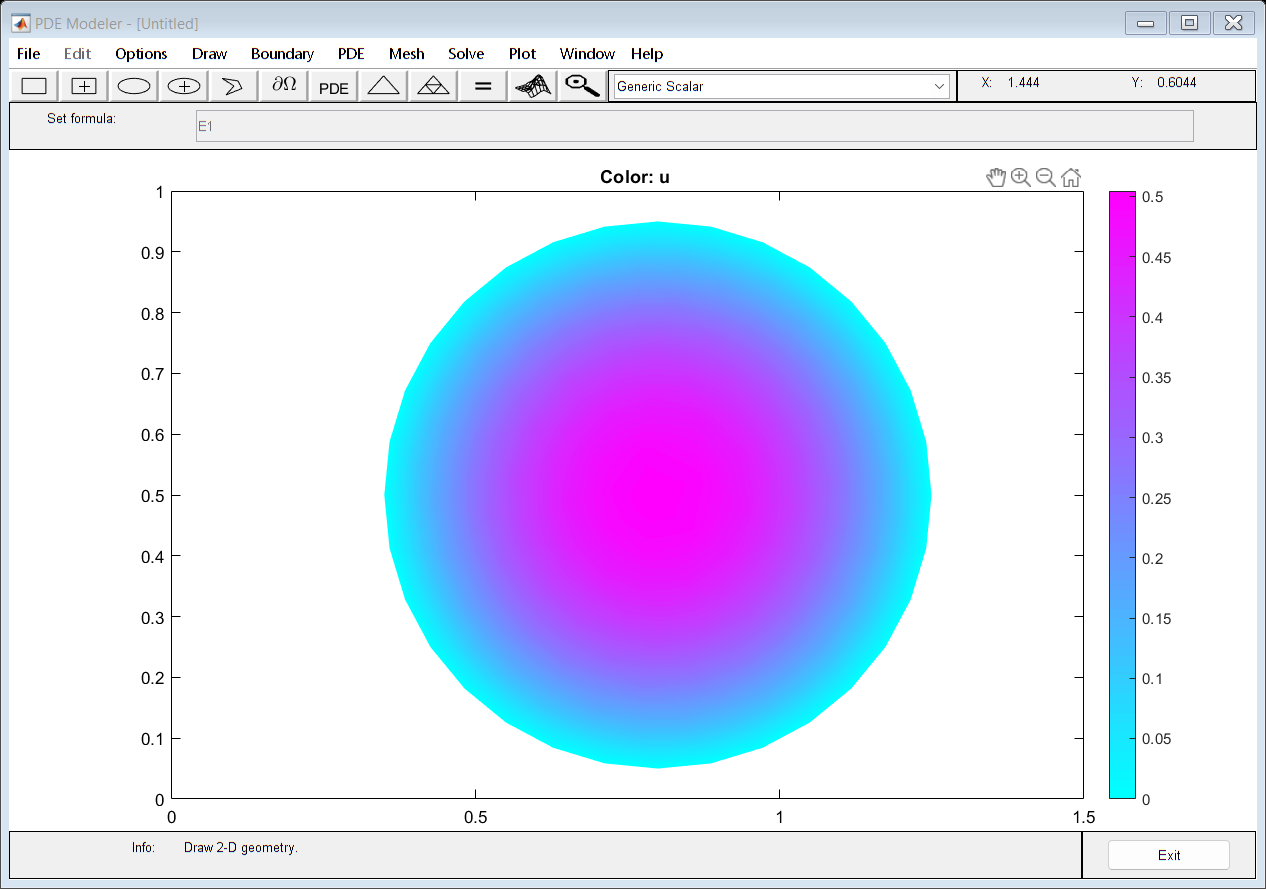

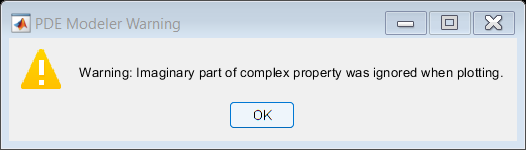

% This script is written and read by pdetool and should NOT be edited.
% There are two recommended alternatives:
% 1) Export the required variables from pdetool and create a MATLAB script
%    to perform operations on these.
% 2) Define the problem completely using a MATLAB script. See
%    https://www.mathworks.com/help/pde/examples.html for examples
%    of this approach.
% function pdemodel
[pde_fig,ax]=pdeinit;
pdetool('appl_cb',1);
set(ax,'DataAspectRatio',[1 1 1]);
set(ax,'PlotBoxAspectRatio',[1.5 1 2]);
set(ax,'XLim',[0 1.5]);
set(ax,'YLim',[0 1]);
set(ax,'XTickMode','auto');
set(ax,'YTickMode','auto');

% Geometry description:
pdeellip(0.80000000000000004,0.5,0.45000000000000001,0.45000000000000001,...
0,'E1');
set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','E1')

% Boundary conditions:
pdetool('changemode',0)
pdesetbd(4,...
'neu',...
1,...
'-60i',...
'0')
pdesetbd(3,...
'neu',...
1,...
'-60i',...
'0')
pdesetbd(2,...
'neu',...
1,...
'-60i',...
'0')
pdesetbd(1,...
'neu',...
1,...
'-60i',...
'0')

% Mesh generation:
setappdata(pde_fig,'Hgrad',1.3);
setappdata(pde_fig,'refinemethod','regular');
setappdata(pde_fig,'jiggle',char('on','mean',''));
setappdata(pde_fig,'MesherVersion','preR2013a');
pdetool('initmesh')

% PDE coefficients:
pdeseteq(1,...
'1.0',...
'0.0',...
'10.0',...
'1.0',...
'0:10',...
'0.0',...
'0.0',...
'[0 100]')
setappdata(pde_fig,'currparam',...
['1.0 ';...
'0.0 ';...
'10.0';...
'1.0 '])

% Solve parameters:
setappdata(pde_fig,'solveparam',...
char('0','1000','10','pdeadworst',...
'0.5','longest','0','1E-4','','fixed','Inf'))

% Plotflags and user data strings:
setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 0 0 0 1 1 0 0 0 0 1]);
setappdata(pde_fig,'colstring','');
setappdata(pde_fig,'arrowstring','');
setappdata(pde_fig,'deformstring','');
setappdata(pde_fig,'heightstring','');

% Solve PDE:
pdetool('solve')

به صورت یک تحلیل کلی می توان گفت همانطور که در شکل مشخص ایت موج ما از مرکز به سمت اطراف گسترش می باید به همین دلیل شدت آن در مرکز بیشتر است و با توجه به دایره ای که در ابتدا تعریف کردیم این گسترش به صورت شعاعی و متقارن در این دایره صورت می گیرد.

**functions of first part (because of version of my matlab i should decleare them at the end of the file.)**

function ic = IC_definer(x)
    ic = 2*exp(x);
end

function [pl, ql, pr, qr] = BC_definer(xl, ul, xr, ur, t)
    pl = ul;
    ql = 0;
    pr = ur - 35;
    qr = 0; 
end

### correspondence to the definition of pde in matlab


$$50\frac{\partial u}{\partial x}=\frac{\partial^2 u}{\partial x^2 }$$



$$\Rightarrow c=50$$



$$\Rightarrow \;f=\frac{\;\partial u}{\partial x}$$



$$\Rightarrow s=0$$



$$\Rightarrow m=0$$


function [c, f, s, m] = set_coefficients(x, t, u, DuDx)
    c = 50;
    f = DuDx;
    s = 0;
end